# Reciprocal

This script generates plots for the figure that shows analysis of reciprocal architectures.


% Standard MATLAB initialization
clear; clc; clf; % reset workspace
rng default; % explicitly seed random numbers (for reproducibility)

% Ensure the following line is not commented out to display version information
% ver

## Define Styles

% All styling variables are placed in the global workspace so they can be
% conveniently accessed by plotting functions. Suppress the MATLAB warning.
global FontName; %#ok<*GVMIS>
FontName   = "Arial";

global C4Color C12Color MixedColor LasBColor LasIColor RhlIColor;
C4Color    = [237,176,129]/255;
C12Color   = [193,65,104]/255;
MixedColor = [229,113,94]/255;
LasBColor  = [44,49,114]/255;
LasIColor  = [165,205,144]/255;
RhlIColor  = [52,133,141]/255;

% Custom color maps adapted from seaboarn: 
%  - Watson ML. “seaborn: statistical data visualization.” Journal of Open Source
%  - Software 2021 Apr 06;6(60): doi: 10.21105/joss.03021.
global crest flare; %#ok<NUSED>
load("crest.mat");
load("flare.mat");

## Load Data and Model Parameters

% Retrieve model parameter estimates. Since these values are
% used throughout the notebook, they're stored as global data
% to avoid Workspace clutter and verbose function signatures.

loadModel();
% global Model; % uncomment this line to expose model to workspace

lasI = readData("LasIObservations.csv");
rhlI = readData("RhlIObservations.csv");
lasB = readData("LasBObservations.csv");

## Create the Plots in the Figure

### Main Plots

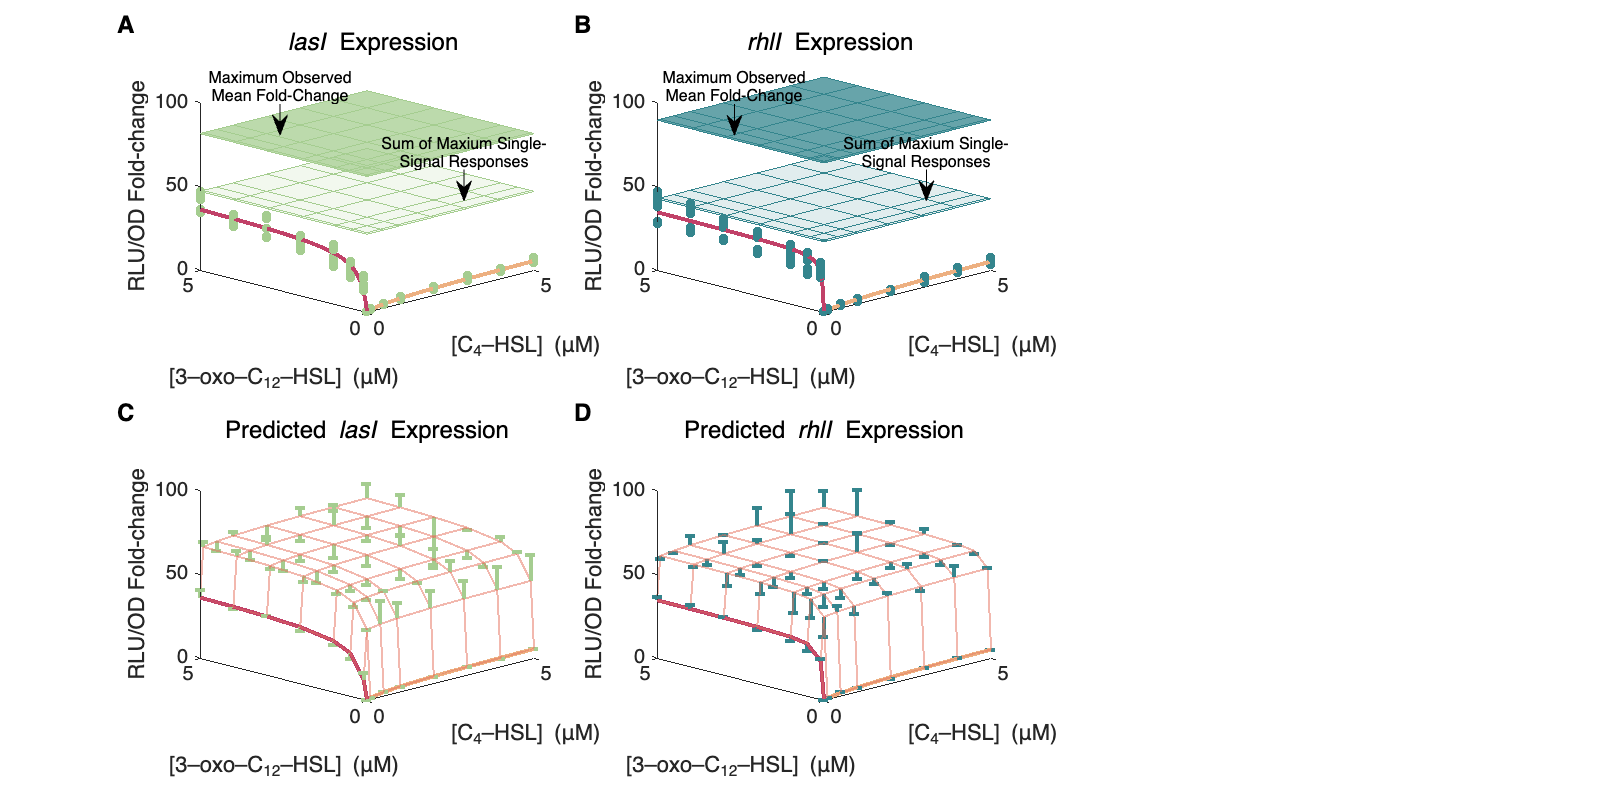

fig = figure;
fig.Position(3:4) = [800, 400];  % [width, height]

reciprocalPlot = tiledlayout(2, 3);
nexttile;
PlotWithCeiling(Data=lasI, gene="lasI", Panel="A");
nexttile;
PlotWithCeiling(Data=rhlI, gene="rhlI", Panel="B");
nexttile(4);
PlotModel(Data=lasI, gene="lasI", Panel="C");
nexttile(5);
PlotModel(Data=rhlI, gene="rhlI", Panel="D");

exportgraphics(reciprocalPlot, "../Prefigures/reciprocal.png", Resolution=600);
exportgraphics(reciprocalPlot, "../Prefigures/reciprocal.pdf", ContentType='vector');

### Secondary Plots for lasB

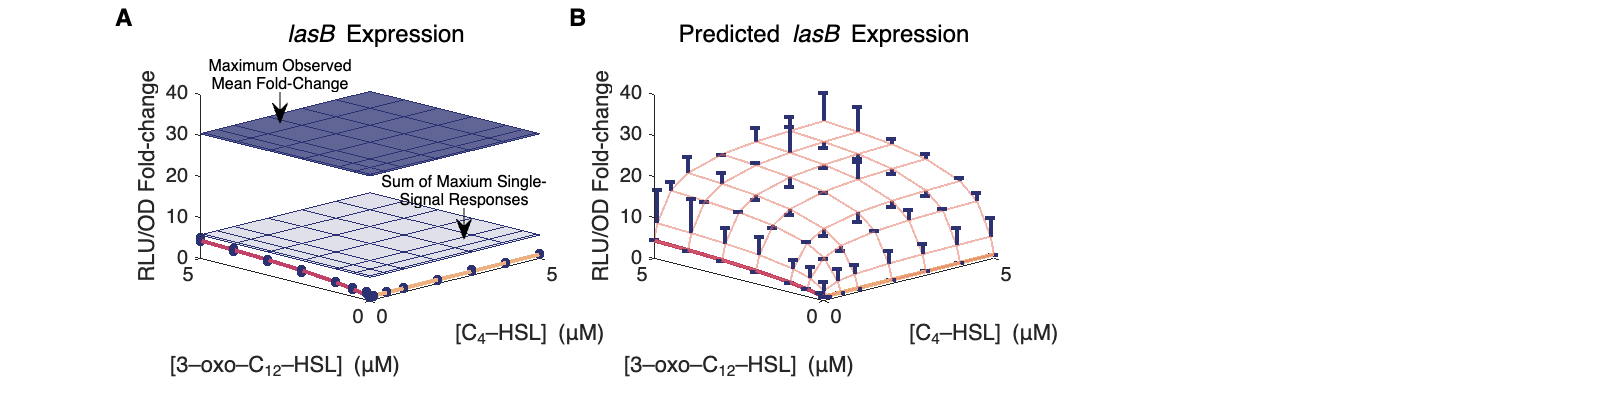

fig = figure;
fig.Position(3:4) = [800, 200];  % [width, height]

lasBPlot = tiledlayout(1, 3);
nexttile;
PlotWithCeiling(Data=lasB, gene="lasB", Panel="A");
nexttile;
PlotModel(Data=lasB, gene="lasB", Panel="B");

exportgraphics(lasBPlot, "../Prefigures/lasb.png", Resolution=600);
exportgraphics(lasBPlot, "../Prefigures/lasb.pdf", ContentType='vector');

## Local Functions

function [data, meanData] = readData(fileName)
    arguments (Input)
        fileName string % file name without path
    end
    arguments (Output)
        data table      % table of all observations
        meanData table  % table of mean expression per replicate
    end

    data = readtable("../Models/" + fileName);
    meanData = groupsummary(data, ["c12","c4"], "mean", "rlu_od");
    meanData = renamevars(meanData, "mean_rlu_od", "rlu_od");
    meanData.GroupCount = [];
end

function loadModel()
    global Model;
    global a10 a11 K11 a12 K12 a112 K112 K121;
    global a20 a21 K21 a22 K22 a212 K212 K221;
    global a30 a31 K31 a32 K32 a312 K312 K321;

    Model = readtable("../Models/Summary.csv", 'ReadRowNames', true);
    GenesRegex = regexpPattern('lasI|rhlI|lasB');
    Model.Properties.RowNames = cellfun(@(str) ...
        extract(str, GenesRegex), Model.Properties.RowNames);
    Model = fillmissing(Model, 'constant', 0);

    a10 = Model{"lasI", "a0"};
    a11 = Model{"lasI", "a_c12"};
    K11 = Model{"lasI", "K_c12"};
    a12 = Model{"lasI", "a_c4"};
    K12 = Model{"lasI", "K_c4"};
    a112 = Model{"lasI", "aQ"};
    K112 = Model{"lasI", "KQ_c12"};
    K121 = Model{"lasI", "KQ_c12"};

    a20 = Model{"rhlI", "a0"};
    a21 = Model{"rhlI", "a_c12"};
    K21 = Model{"rhlI", "K_c12"};
    a22 = Model{"rhlI", "a_c4"};
    K22 = Model{"rhlI", "K_c4"};
    a212 = Model{"rhlI", "aQ"};
    K212 = Model{"rhlI", "KQ_c12"};
    K221 = Model{"rhlI", "KQ_c12"};

    a30 = Model{"lasB", "a0"};
    a31 = Model{"lasB", "a_c12"};
    K31 = Model{"lasB", "K_c12"};
    a32 = Model{"lasB", "a_c4"};
    K32 = Model{"lasB", "K_c4"};
    a312 = Model{"lasB", "aQ"};
    K312 = Model{"lasB", "KQ_c12"};
    K321 = Model{"lasB", "KQ_c12"};
end

function handle = PlotWithCeiling(args)
    arguments
        args.Data  table;
        args.Gene  string;
        args.Panel string = "";
    end

    global LasIColor RhlIColor LasBColor;
    global C4Color C12Color;
    global a10 a11 a12 K11 K12; % lasI parameters (i=1)
    global a20 a21 a22 K21 K22; % rhlI parameters (i=2)
    global a30 a31 a32 K31 K32; % rhlI parameters (i=3)

    data   = args.Data;
    gene   = args.Gene;
    panel  = args.Panel;

    if gene == "lasI"
        color = LasIColor;
        a0 = a10; a1 = a11; a2 = a12;
        K1 = K11; K2 = K12;
        labels = [[0.175 0.175]; [0.87 0.831]; [0.29 0.29]; [0.788 0.749]];
        limit = 100;
    elseif gene == "rhlI"
        color = RhlIColor;
        a0 = a20; a1 = a21; a2 = a22;
        K1 = K21; K2 = K22;
        labels = [[0.459 0.459]; [0.87 0.831]; [0.579 0.579]; [0.788 0.749]];
        limit = 100;
    elseif gene == "lasB"
        color = LasBColor;
        a0 = a30; a1 = a31; a2 = a32;
        K1 = K31; K2 = K32;
        labels = [[0.175 0.175]; [0.77 0.692]; [0.29 0.29]; [0.48 0.402]];
        limit = 40;
    end

    c12Values = unique(data.c12);
    c4Values = unique(data.c4);

    c12Range = linspace(min(c12Values), max(c12Values), 100);
    c12Predictions = (a0 + a1 * c12Range ./ (K1 + c12Range)) / a0;

    c4Range = linspace(min(c4Values), max(c4Values), 100);
    c4Predictions = (a0 + a2 * c4Range ./ (K2 + c4Range)) / a0;

    c4Data = data(data.c12 == 0, :);
    c12Data = data(data.c4 == 0, :);

    meanData = groupsummary(data, ["c12","c4"], "mean", "rlu_od");

    baseline = mean(data{data.c4 == 0 & data.c12 == 0, 'rlu_od'});
    maxSum = max(meanData{meanData.c4 == 0, 'mean_rlu_od'} + ...
        meanData{meanData.c12 == 0, 'mean_rlu_od'});
    maxTotal = max(meanData.mean_rlu_od);

    hold on;

    % Show the maximum expression "ceiling"
    handle = surf(c4Values, c12Values, ...
        (maxTotal / baseline) * ones(length(c4Values), length(c12Values)), ...
        FaceColor=color, EdgeColor=color, FaceAlpha=0.75);
    annotation("textarrow", labels(1,:), labels(2,:), ...
        String={'Maximum Observed', 'Mean Fold-Change'}, FontSize=8);

    % Show the maximum sum
    surf(c4Values, c12Values, ...
        (maxSum / baseline) * ones(length(c4Values), length(c12Values)), ...
        FaceColor=color, EdgeColor=color, FaceAlpha=0.15);
    annotation("textarrow", labels(3,:), labels(4,:), ...
        String={'Sum of Maxium Single-', 'Signal Responses'}, FontSize=8);
    
    % Show RLU/OD observations for each signal alone
    plot3(c12Data.c4, c12Data.c12, c12Data.rlu_od / baseline, ...
        '.', MarkerSize=15, MarkerEdgeColor=color, MarkerFaceColor=color);
    plot3(c4Data.c4, c4Data.c12, c4Data.rlu_od / baseline, ...
        '.', MarkerSize=15, MarkerEdgeColor=color, MarkerFaceColor=color);

    % Add lines for predictions
    plot3(zeros(size(c4Range)), c12Range, c12Predictions, ...
        LineWidth=2, Color=C12Color);
    plot3(c4Range, zeros(size(c12Range)), c4Predictions, ...
        LineWidth=2, Color=C4Color);

    view(-45, 20);

    xlabel("[C_4–HSL] (μM)");
    ylabel("[3–oxo–C_{12}–HSL] (μM)");
    zlabel("RLU/OD Fold-change");
    zlim([0 limit]);
    title("\it " + gene + "\rm Expression", FontWeight="normal", FontSize=12);

    hold off;

    if panel ~= ""
        text(-0.25, 1.2, panel, ...
            Units="normalized", ...
            HorizontalAlignment="left", VerticalAlignment="top", ...
            FontSize=12, FontWeight="bold");
    end
end

function handle = PlotModel(args)
    arguments
        args.Data  table;
        args.Gene  string;
        args.Panel string = "";
    end

    global LasIColor RhlIColor LasBColor;
    global C4Color C12Color MixedColor;
    global a10 a11 a12 K11 K12 a112 K112 K121; % lasI parameters (i=1)
    global a20 a21 a22 K21 K22 a212 K212 K221; % rhlI parameters (i=2)
    global a30 a31 a32 K31 K32 a312 K312 K321; % rhlI parameters (i=3)

    data   = args.Data;
    gene   = args.Gene;
    panel  = args.Panel;

    if gene == "lasI"
        color = LasIColor;
        a0 = a10; a1 = a11; a2 = a12;
        K1 = K11; K2 = K12;
        ax = a112; Kx1 = K112; Kx2 = K121;
        limit = 100;
    elseif gene == "rhlI"
        color = RhlIColor;
        a0 = a20; a1 = a21; a2 = a22;
        K1 = K21; K2 = K22;
        ax = a212; Kx1 = K212; Kx2 = K221;
        limit = 100;
    elseif gene == "lasB"
        color = LasBColor;
        a0 = a30; a1 = a31; a2 = a32;
        K1 = K31; K2 = K32;
        ax = a312; Kx1 = K312; Kx2 = K321;
        limit = 40;
    end

    % K values can be very small. To avoid division by 0, enforce a minimum
    % value for all of them.
    Kmin = 1e-20;
    K1 = max(K1, Kmin);
    K2 = max(K2, Kmin);
    Kx1 = max(Kx1, Kmin);
    Kx2 = max(Kx2, Kmin);

    c12Values = unique(data.c12);
    c4Values = unique(data.c4);

    baseline = mean(data{data.c4 == 0 & data.c12 == 0, 'rlu_od'});

    data = groupsummary(data, ["c12","c4"], "mean", "rlu_od");
    data = renamevars(data, "mean_rlu_od", "rlu_od");
    data.GroupCount = [];

    data.predicted = a0 + ...
        (a1 * data.c12 ./ (K1 + data.c12)) + ...
        (a2 * data.c4 ./ (K2 + data.c4)) + ...
        (ax * data.c4 .* data.c12 ./ ((Kx1 + data.c12) .* (Kx2 + data.c4)));
    data.residuals = data.predicted - data.rlu_od;

    hold on;

    predicted = transpose(reshape(data.predicted / a0, ...
        length(c4Values), length(c12Values)));

    mesh(c4Values, c12Values, predicted, ...
        FaceAlpha=0, EdgeColor=MixedColor, EdgeAlpha=0.5, LineWidth=1);

    % Emphasize C4- and C12-only predictions
    plot3(c4Values, 0 * c12Values, predicted(1, :), Color=C4Color, LineWidth=2);
    plot3(0 * c4Values, c12Values, predicted(:, 1), Color=C12Color, LineWidth=2);

    quiver3(data.c4, data.c12, data.rlu_od / baseline, ...
        0 * data.c4, 0 * data.c12, data.residuals / baseline, ...
        'AutoScale', "off", ...
        'Marker', "_", ...
        'ShowArrowHead'," off", ...
        'LineWidth', 2, ...
        'MarkerSize', 5, ...
        'MarkerEdgeColor', color, ...
        'MarkerFaceColor', color, ...
        'Color', color ...
    );

    view(-45, 20);

    xlabel("[C_4–HSL] (μM)");
    ylabel("[3–oxo–C_{12}–HSL] (μM)");
    zlabel("RLU/OD Fold-change");
    zlim([0 limit]);
    title("Predicted\it " + gene + "\rm Expression", FontWeight="normal", FontSize=12);

    hold off;

    if panel ~= ""
        text(-0.25, 1.2, panel, ...
            Units="normalized", ...
            HorizontalAlignment="left", VerticalAlignment="top", ...
            FontSize=12, FontWeight="bold");
    end
end